**Universtiy of Southern California**

**Fall 2020 : EE 510**

**Discussion Session 2: Introduction to Matlab **

**September 4, 2020**

% Matrix Genreation
x=[1 2 3 4]

x =      1     2     3     4


y=[5;6;7;8]

y =      5
     6
     7
     8


x*y

ans = 70

A=zeros(3,3)

A =      0     0     0
     0     0     0
     0     0     0


A=eye(3)

A =      1     0     0
     0     1     0
     0     0     1


A=ones(3)

A =      1     1     1
     1     1     1
     1     1     1


A=rand(3,4)

A =     0.8147    0.9134    0.2785    0.9649
    0.9058    0.6324    0.5469    0.1576
    0.1270    0.0975    0.9575    0.9706


A=[1 2 3;4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


A'

ans =      1     4     7
     2     5     8
     3     6     9


% Second row
A(2,:)

ans =      4     5     6


% Sub matrix: the last two columns
A(:,2:3)

ans =      2     3
     5     6
     8     9


% Delete th second column (null vector: [])
A(:,2)=[]

A =      1     3
     4     6
     7     9


% Create a sub matrix B from A
B=A([2 3],[1 2])

B =      4     6
     7     9


%% Loops and Controls
%% If Statement
a=3;
b=5;
if (a > b)
        disp(' a is greater than b');
else
    disp(' b is greater than a')
end    

 b is greater than a


  %% While loop
a = 1;
while a < 50
      disp(a);
      a = a*3; 
end  

     1



     3



     9



    27



%% For loop
for i=1:10
    disp(i)
end

     1



     2



     3



     4



     5



     6



     7



     8



     9



    10



%% Switch statement
Val = 'Fall2020';
switch Val 
    case 1
        disp('one');
    case 2
        disp('two');
    case 'Fall2020'
        disp(Val);
    otherwise
    disp('other');
end

Fall2020


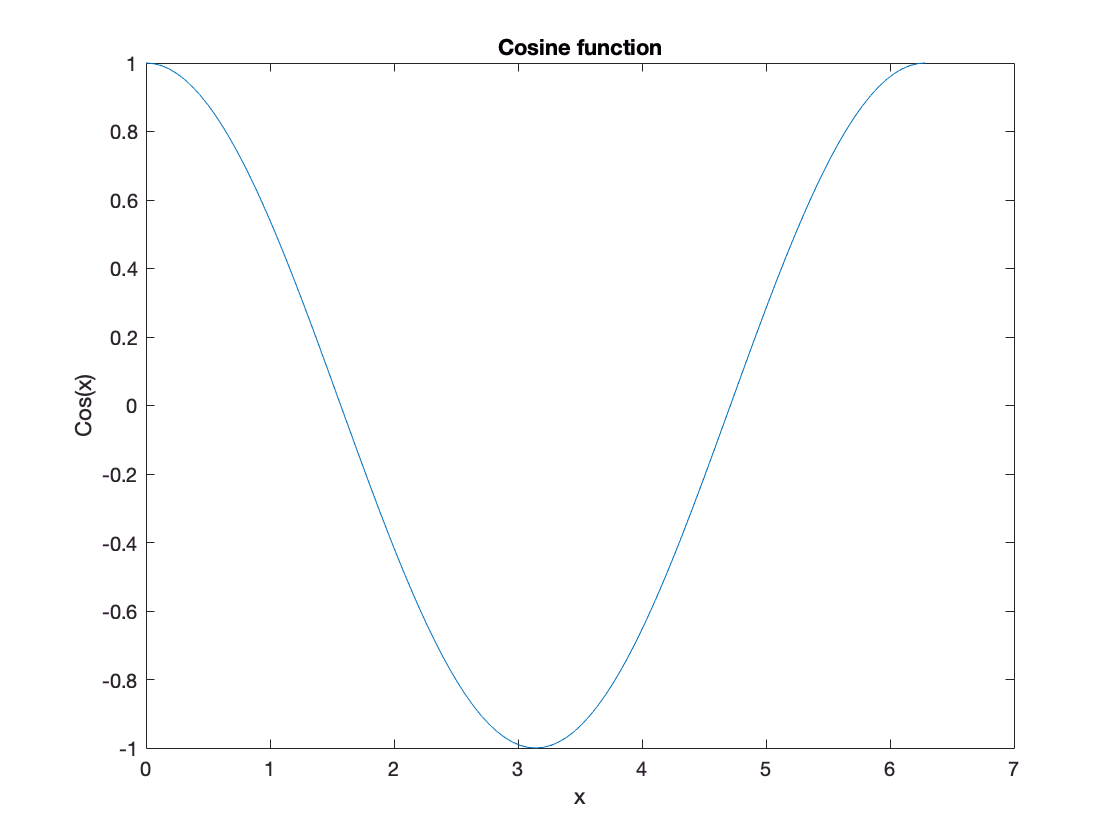

%% Plot data
x = 0:pi/50:2*pi;
y = cos(x);
figure
plot(x,y)
xlabel('x')
ylabel('Cos(x)')
title('Cosine function')

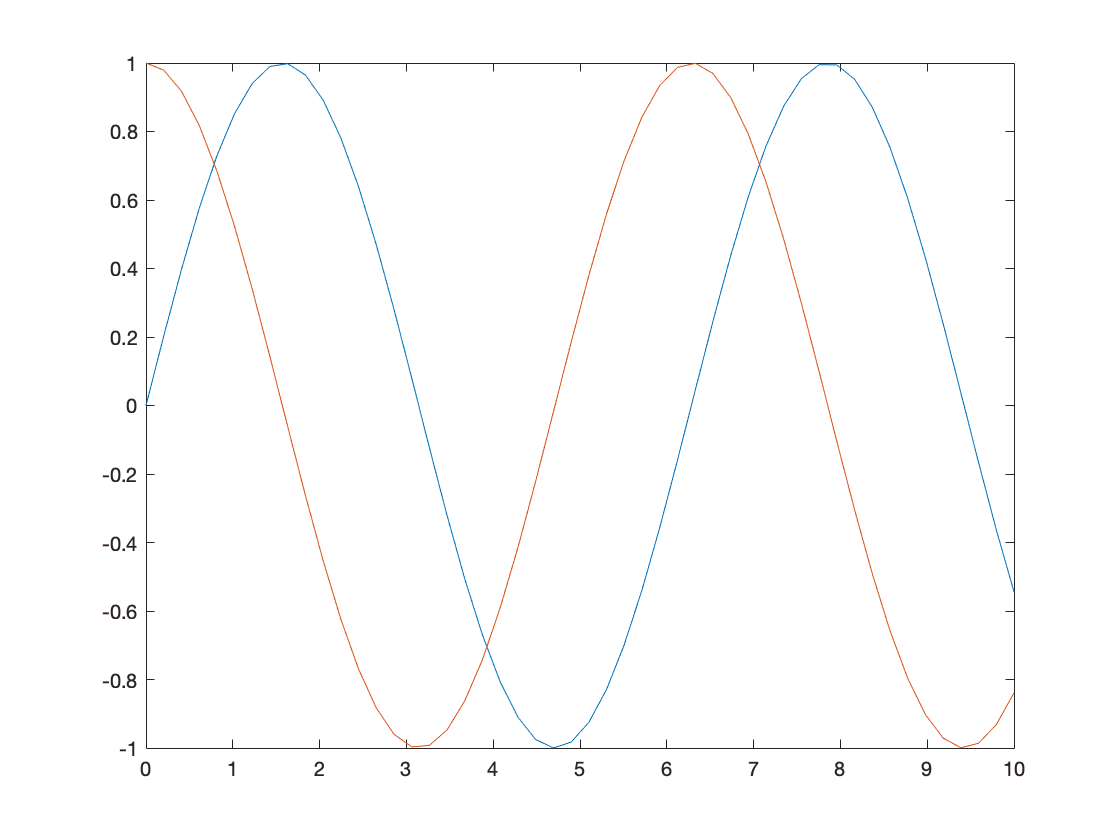

% Plot two datasets
x = linspace(0,10,50);
y = sin(x);
z = cos(x);
figure
plot(x,y)
hold on 
plot(x,z)

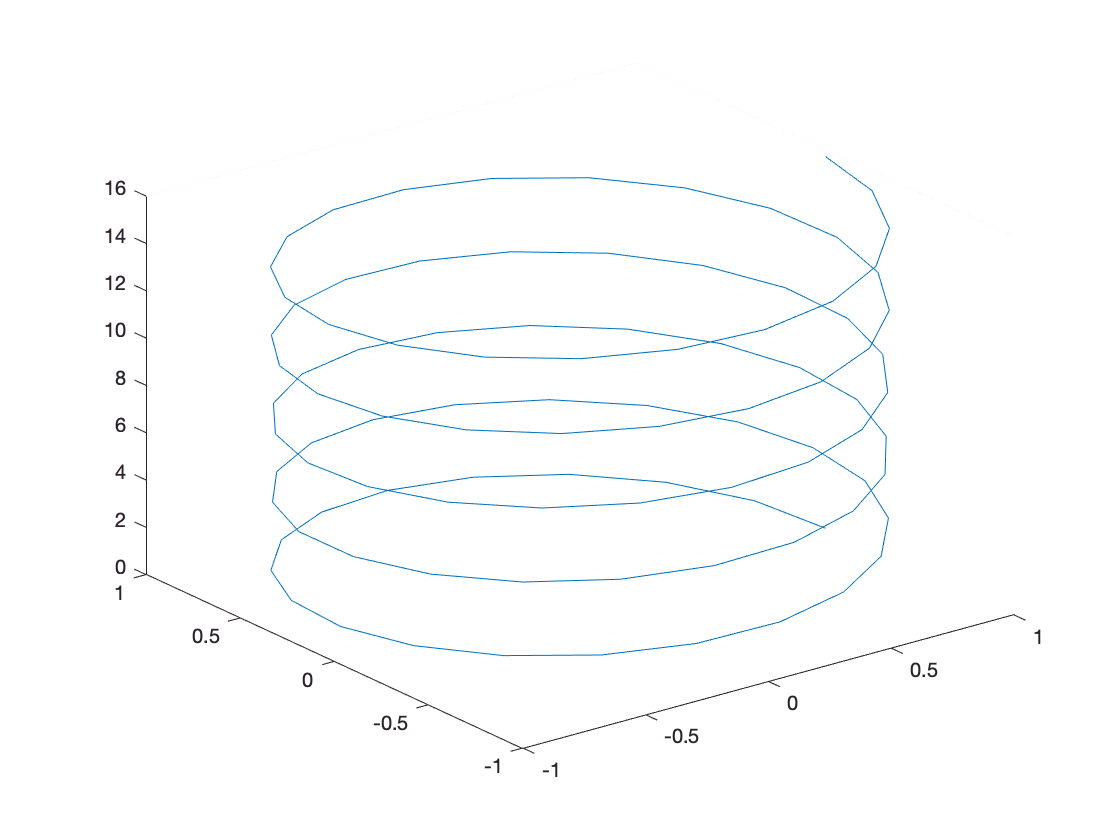

%% Plot parameteric curve
t = linspace(0,10*pi,100);
x = cos(t);
y = sin(t);
z = 0.5*t;
figure
plot3(x,y,z)

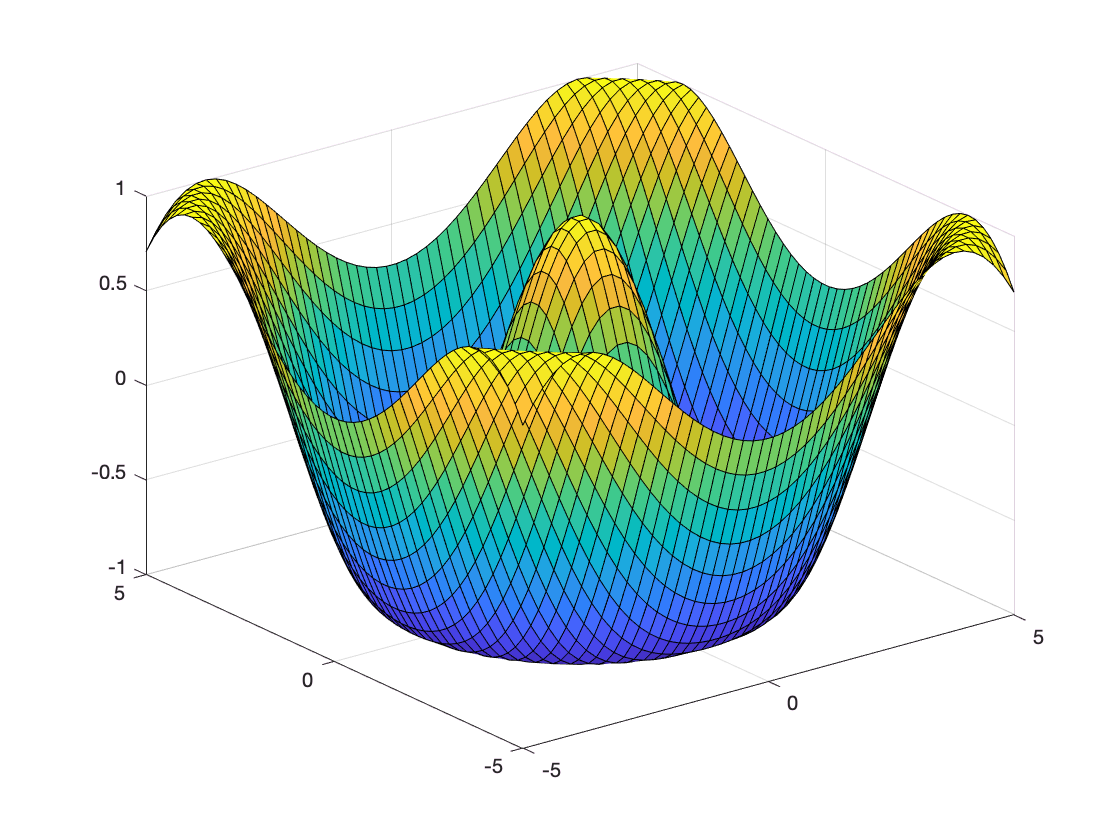

%% Plot 3D 
f = @(x,y) cos(sqrt(x.^2 + y.^2));
x = linspace(-5,5,50);
y = linspace(-5,5,50);
figure
[X_data,Y_data] = meshgrid(x,y); 
h_plot = surf(X_data,Y_data,f(X_data,Y_data)); 

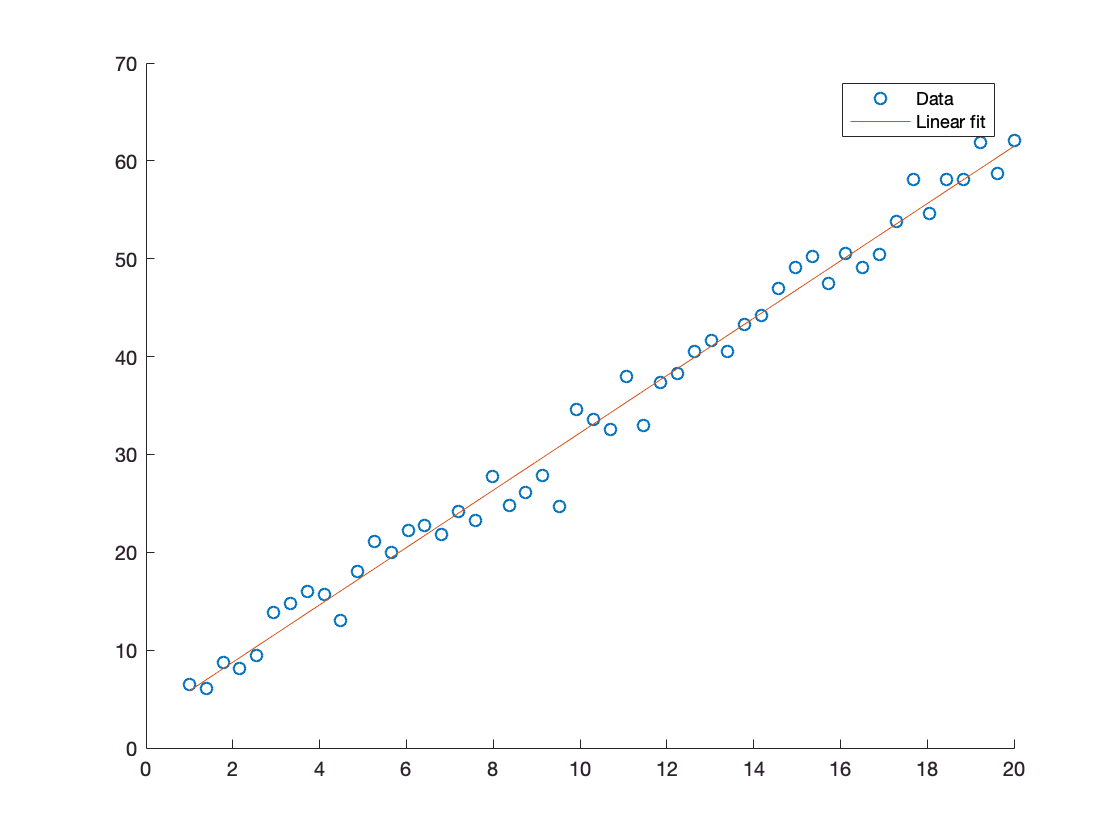

%% Data visualization
x=linspace(1,20,50);
y=3*x+2+2*randn(1,50);
figure
scatter(x,y)
p = polyfit(x,y,1); 
f = polyval(p,x);
hold on
plot(x,f,'-') 
legend('Data','Linear fit') 

%% Matlab performance
% Example
x = rand(1,10^3);
y = zeros(1,10^3); 
starttime=cputime;
for i = 1:10^3
    y(i) = exp(x(i));
end
endtime=cputime;
time=endtime-starttime

time = 0.5000

% For loop is replaced by a parallel evaluation
starttime_1=cputime;
y = exp(x);
endtime_1=cputime;
time1=endtime_1-starttime_1

time1 = 0.0800

x=pi/2;
n=1000;
y=Sum(x,n)

y = 1.0003

% Define a function to calculate the following summation given n and x as inputs


$$S_n \left(x\right)=\frac{4}{\pi }\sum_{k=1}^{n} \frac{\mathrm{sin}\left(\left(2k+1\right)x\right)}{2k+1}$$


function y = Sum(x,n) 
    c=4/pi;
    % initial value of the summation 
    s = 0; 
    for k =1:2*n+1 
        if mod(k,2)==1
            s=s+1/k*sin(k*x);
        end
    end 
    y = c*s;
end